Sc0 = 240;
Sa0 = 740;
Ic0 = 10;
Ia0 = 10;
Ec0 = 0;
Ea0 = 0;
Rc0 = 0;
Ra0 = 0;
Nc0 = Sc0 + Ic0 + Ec0 + Rc0;
Na0 = Sa0 + Ia0 + Ea0 + Ra0;
daily = 1:1:365;
init_cond = [Sc0, Sa0, Ec0, Ea0, Ic0, Ia0, Rc0, Ra0, Nc0, Na0];
par = [0.00027 0.074 0.1 0.3 0.5];%.00027 0.074 0.1 0.3 0.2

[t,yc]=ode45(@SEIR_model_states_AdultChild_depB,daily,init_cond,[],[par(1), par(2), par(3), par(4), par(5)]);
[Pc,t_index] = max(yc(:,5));
Ptc = t(t_index)

Ptc = 58

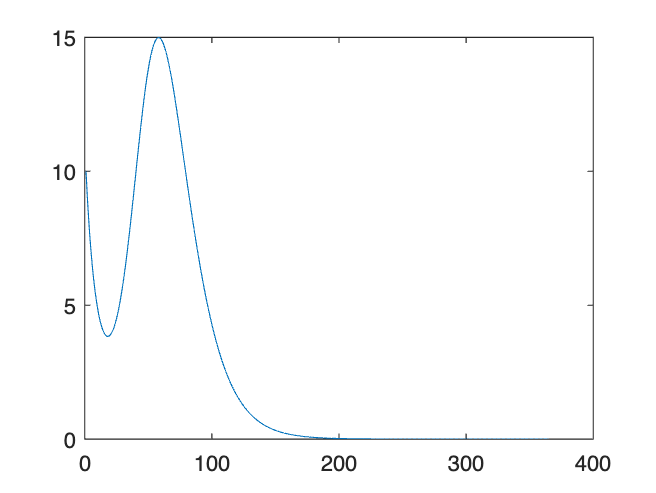

plot(t, yc(:,5))

[t,ya]=ode45(@SEIR_model_states_AdultChild_depB,daily,init_cond,[],[par(1), par(2), par(3), par(4), par(5)]);
[Pa,t_index] = max(ya(:,6));
Pta = t(t_index)

Pta = 48

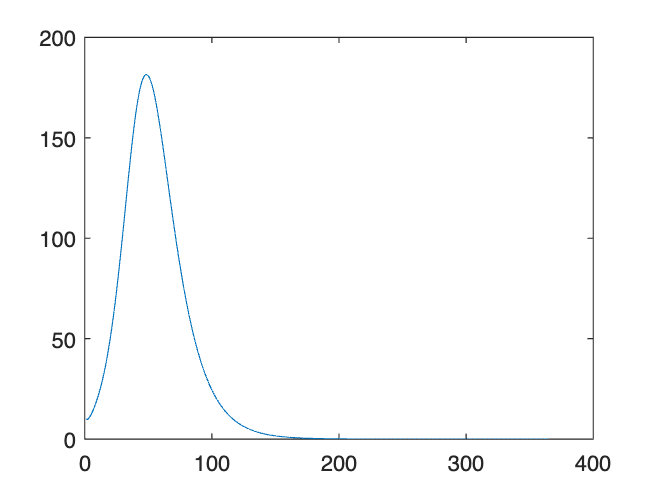

plot(t,ya(:,6))